# Alinea A

N = 1e6;
alvos = 100;
dardos = 20;

experiencias = zeros(alvos,N); % matriz com 100 linhas (alvos) e N colunas
                                % (numero de experiencias)

for j = 1:N
    for i = 1:dardos
        lineNum = randi([1 100]); % seleciona linha aleatoria coluna atual
        experiencias(lineNum,j) = experiencias(lineNum,j) + 1; % incrementa o numero de dardos no alvo
    end
end

acertou_uma_vez = experiencias == 1; %seleciona os alvos acertados uma vez
acertou_uma_vez = sum(acertou_uma_vez); % soma do numero de alvos atingidos numa experiencia
acertou_uma_vez = acertou_uma_vez == 20; % 20 alvos atingidos uma vez

prob = sum(acertou_uma_vez)/N

prob = 0.1307

## Alinea B

N = 1e6;
alvos = 100;
dardos = 20;

experiencias = zeros(alvos,N); % matriz com 100 linhas (alvos) e N colunas
                                % (numero de experiencias)

for j = 1:N
    for i = 1:dardos
        lineNum = randi([1 alvos]); % seleciona linha aleatoria coluna atual
        experiencias(lineNum,j) = experiencias(lineNum,j) + 1; % incrementa o numero de dardos no alvo
    end
end

acertou_duas_ou_mais = experiencias >= 2; % seleciona os alvos acertados duas ou mais
soma_alvos = sum(acertou_duas_ou_mais); % soma do numero de alvos acertados duas ou mais
um_ou_mais_alvos = soma_alvos >= 1; % um ou mais alvos ter sido acertado

prob = sum(um_ou_mais_alvos)/N

prob = 0.8700

## Ainea C

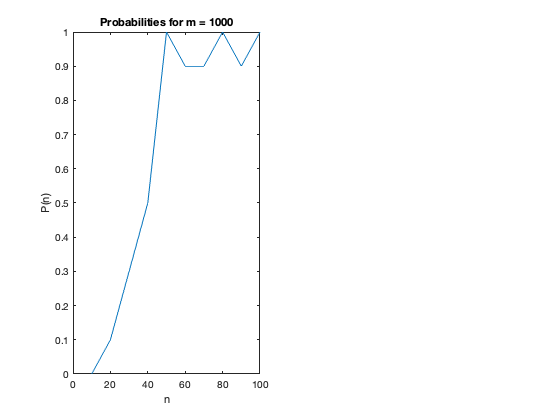

N = 10;
m = 1000;
nValues = 1:10;

prob = zeros(1,10);

for n = 1:length(nValues)
    experiencia = randi(m,10*n,N); % colunas com o numero do alvo acertado
    sucesso = 0;
    
    for j = 1:N % para cada experiencia
        if(length(unique(experiencia(:,j))) ~= 10*n) % se um alvo foi atingido pelo menos duas vezes
            sucesso = sucesso + 1; % sucesso
        end
    end
    prob(n) = sucesso / N;
end

figure
subplot(1,2,1)
plot(nValues*10,prob)
xlabel('n')
ylabel('P(n)')
title('Probabilities for m = 1000')
drawnow
pause()


m = 100000;
N = 10;
nValues = 1:10;
prob = zeros(1,10);
i = 1;

for n = 1 : length(nValues)
    experience = ceil(m * rand (n, N));                % Columns have the number of the target the darts hit
    successes  = 0;

    parfor j = 1:  N                                   % For each experience
        if (length (unique(experience(:,j))) ~= n)     % if at least 1 number is different, ie at least 1 target were hit at least twice
            successes =  successes + 1;                % it's a success
        end
    end
    
    prob(i) = successes / N;
    
    n = n + 10;
    i = i + 1;
end

subplot(2,2,2)
plot(nValues, prob)  
xlabel('n')
ylabel('P(n)')
title('Probabilities for m = 100000')

